%select teh top 200 columns and run the analysis on them

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
% subjready={7403,7404,7444, 7484}
subjready={7375, 7361, 7376,7383, 7402, 7403, 7404,7405, 7408, 7414, 7415};


subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
allsubjlayer={};
for subj=allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_S1raw.mat'];
    if exist(columnartsfile,"file")
%         disp(subj)
        disp([num2str(subj{:}) ' subject columnar info r'])
        plotidx=plotidx+1;
        [stat,columndistribution,layerwisestat]=BK_layer_sampling_pain_study_pipeline(subj,'glmestimate','S1','raw','no');
        allsubjid(plotidx)=subj{:};
        allsubjlayer{plotidx}=layerwisestat;
        allsubjcoldistr{plotidx}=columndistribution;
        allsubjstat{plotidx}=stat;
%         subplot(subplotsize(1), subplotsize(2), plotidx);
%         hcogn=histogram(stat.T(:,:,1),'BinLimits',[-5,5],'FaceColor', 'blue');
%         hold on
%         hpain=histogram(stat.T(:,:,2),'BinLimits',[-5,5],'FaceColor', 'red');
%         hconj=histogram(stat.T(:,:,3),'BinLimits',[-5,5],'FaceColor', 'green');
%         xline(1,'-','LineWidth', 1.5,'Color', 'blue');
%         xline(0,'-','LineWidth', 1.5,'Color', 'red');
%         title(num2str(subj{:}))
%         if plotidx==1
%             legend('Cognitive act (Blue)', 'Pain act (Red)','Conjuction act (Blue)','t>1', 'Location', 'northwestoutside');
%         end
%         
%         hold off
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject columnar info r


Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The number of columns acitvating in each run(t>0) for cognition: 206
Subject:7349The number of columns acitvating in each run(t>0) for pain: 496
Subject:7349The number of columns acitvating in each run(t>0) for cognition AND pain: 143
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The number of columns acitvating in each run(t>1) for cognition: 50
Subject:7349The number of columns acitvating in each run(t>1) for pain: 206
Subject:7349The number of columns acitvating in each run(t>1) for cognition AND pain: 19
-------------------------------------------------------------


Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The number of columns acitvating in each run(t>0) for cognition: 658
Subject:7349The number of columns acitvating in each run(t>0) for pain: 1265
Subject:7349The number of columns acitvating in each run(t>0) for cognition AND pain: 465
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The number of columns acitvating in each run(t>1) for cognition: 237
Subject:7349The number of columns acitvating in each run(t>1) for pain: 671
Subject:7349The number of columns acitvating in each run(t>1) for cognition AND pain: 113
-------------------------------------------------------------
time for laminar activation:Elapsed time is 6.021224 seconds.
Time for one subject to process:Elapsed time is 6.072031 seconds.


7356 subject columnar info r


Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The number of columns acitvating in each run(t>0) for cognition: 421
Subject:7356The number of columns acitvating in each run(t>0) for pain: 314
Subject:7356The number of columns acitvating in each run(t>0) for cognition AND pain: 188
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The number of columns acitvating in each run(t>1) for cognition: 171
Subject:7356The number of columns acitvating in each run(t>1) for pain: 108
Subject:7356The number of columns acitvating in each run(t>1) for cognition AND pain: 24
-------------------------------------------------------------


Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The number of columns acitvating in each run(t>0) for cognition: 807
Subject:7356The number of columns acitvating in each run(t>0) for pain: 649
Subject:7356The number of columns acitvating in each run(t>0) for cognition AND pain: 393
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The number of columns acitvating in each run(t>1) for cognition: 322
Subject:7356The number of columns acitvating in each run(t>1) for pain: 215
Subject:7356The number of columns acitvating in each run(t>1) for cognition AND pain: 51
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.780622 seconds.
Time for one subject to process:Elapsed time is 3.816826 seconds.


7361 subject columnar info r


Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 378
Subject:7361The number of columns acitvating in each run(t>0) for pain: 550
Subject:7361The number of columns acitvating in each run(t>0) for cognition AND pain: 287
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The number of columns acitvating in each run(t>1) for cognition: 128
Subject:7361The number of columns acitvating in each run(t>1) for pain: 293
Subject:7361The number of columns acitvating in each run(t>1) for cognition AND pain: 60
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 1748
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 824
Subject:7361The number of columns acitvating in each run(t>0) for pain: 1413
Subject:7361The number of 

7375 subject columnar info r


Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 354
Subject:7375The number of columns acitvating in each run(t>0) for pain: 288
Subject:7375The number of columns acitvating in each run(t>0) for cognition AND pain: 171
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The number of columns acitvating in each run(t>1) for cognition: 124
Subject:7375The number of columns acitvating in each run(t>1) for pain: 109
Subject:7375The number of columns acitvating in each run(t>1) for cognition AND pain: 26
-------------------------------------------------------------


Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 841
Subject:7375The number of columns acitvating in each run(t>0) for pain: 1080
Subject:7375The number of columns acitvating in each run(t>0) for cognition AND pain: 504
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The number of columns acitvating in each run(t>1) for cognition: 272
Subject:7375The number of columns acitvating in each run(t>1) for pain: 467
Subject:7375The number of columns acitvating in each run(t>1) for cognition AND pain: 85
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.356758 seconds.
Time for one subject to process:Elapsed time is 5.402482 seconds.


7376 subject columnar info r


Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 458
Subject:7376The number of columns acitvating in each run(t>0) for pain: 510
Subject:7376The number of columns acitvating in each run(t>0) for cognition AND pain: 286
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The number of columns acitvating in each run(t>1) for cognition: 162
Subject:7376The number of columns acitvating in each run(t>1) for pain: 219
Subject:7376The number of columns acitvating in each run(t>1) for cognition AND pain: 40
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 1683
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 774
Subject:7376The number of columns acitvating in each run(t>0) for pain: 1159
Subject:7376The number of 

7383 subject columnar info r


Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 575
Subject:7383The number of columns acitvating in each run(t>0) for pain: 391
Subject:7383The number of columns acitvating in each run(t>0) for cognition AND pain: 239
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The number of columns acitvating in each run(t>1) for cognition: 288
Subject:7383The number of columns acitvating in each run(t>1) for pain: 133
Subject:7383The number of columns acitvating in each run(t>1) for cognition AND pain: 31
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 1655
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 999
Subject:7383The number of columns acitvating in each run(t>0) for pain: 677
Subject:7383The number of c

7402 subject columnar info r


Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 1038
Subject:7402The number of columns acitvating in each run(t>0) for pain: 533
Subject:7402The number of columns acitvating in each run(t>0) for cognition AND pain: 369
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The number of columns acitvating in each run(t>1) for cognition: 503
Subject:7402The number of columns acitvating in each run(t>1) for pain: 130
Subject:7402The number of columns acitvating in each run(t>1) for cognition AND pain: 24
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 3258
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 2582
Subject:7402The number of columns acitvating in each run(t>0) for pain: 1095
Subject:7402The number

7403 subject columnar info r


Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 455
Subject:7403The number of columns acitvating in each run(t>0) for pain: 312
Subject:7403The number of columns acitvating in each run(t>0) for cognition AND pain: 181
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The number of columns acitvating in each run(t>1) for cognition: 161
Subject:7403The number of columns acitvating in each run(t>1) for pain: 68
Subject:7403The number of columns acitvating in each run(t>1) for cognition AND pain: 17
-------------------------------------------------------------


Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 1028
Subject:7403The number of columns acitvating in each run(t>0) for pain: 816
Subject:7403The number of columns acitvating in each run(t>0) for cognition AND pain: 416
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The number of columns acitvating in each run(t>1) for cognition: 391
Subject:7403The number of columns acitvating in each run(t>1) for pain: 242
Subject:7403The number of columns acitvating in each run(t>1) for cognition AND pain: 48
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.483435 seconds.
Time for one subject to process:Elapsed time is 5.543539 seconds.


7404 subject columnar info r


Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 446
Subject:7404The number of columns acitvating in each run(t>0) for pain: 378
Subject:7404The number of columns acitvating in each run(t>0) for cognition AND pain: 221
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The number of columns acitvating in each run(t>1) for cognition: 192
Subject:7404The number of columns acitvating in each run(t>1) for pain: 148
Subject:7404The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 1443
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 883
Subject:7404The number of columns acitvating in each run(t>0) for pain: 857
Subject:7404The number of c

7405 subject columnar info r


Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 591
Subject:7405The number of columns acitvating in each run(t>0) for pain: 442
Subject:7405The number of columns acitvating in each run(t>0) for cognition AND pain: 353
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The number of columns acitvating in each run(t>1) for cognition: 375
Subject:7405The number of columns acitvating in each run(t>1) for pain: 159
Subject:7405The number of columns acitvating in each run(t>1) for cognition AND pain: 80
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 1352
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 1117
Subject:7405The number of columns acitvating in each run(t>0) for pain: 846
Subject:7405The number of 

7408 subject columnar info r


Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 537
Subject:7408The number of columns acitvating in each run(t>0) for pain: 370
Subject:7408The number of columns acitvating in each run(t>0) for cognition AND pain: 214
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The number of columns acitvating in each run(t>1) for cognition: 218
Subject:7408The number of columns acitvating in each run(t>1) for pain: 117
Subject:7408The number of columns acitvating in each run(t>1) for cognition AND pain: 28
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 2238
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 1610
Subject:7408The number of columns acitvating in each run(t>0) for pain: 869
Subject:7408The number of 

7414 subject columnar info r


Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 433
Subject:7414The number of columns acitvating in each run(t>0) for pain: 412
Subject:7414The number of columns acitvating in each run(t>0) for cognition AND pain: 237
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The number of columns acitvating in each run(t>1) for cognition: 175
Subject:7414The number of columns acitvating in each run(t>1) for pain: 144
Subject:7414The number of columns acitvating in each run(t>1) for cognition AND pain: 35
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 1669
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 977
Subject:7414The number of columns acitvating in each run(t>0) for pain: 862
Subject:7414The number of c

7415 subject columnar info r


Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 339
Subject:7415The number of columns acitvating in each run(t>0) for pain: 257
Subject:7415The number of columns acitvating in each run(t>0) for cognition AND pain: 124
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The number of columns acitvating in each run(t>1) for cognition: 114
Subject:7415The number of columns acitvating in each run(t>1) for pain: 59
Subject:7415The number of columns acitvating in each run(t>1) for cognition AND pain: 7
-------------------------------------------------------------


Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 806
Subject:7415The number of columns acitvating in each run(t>0) for pain: 726
Subject:7415The number of columns acitvating in each run(t>0) for cognition AND pain: 344
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The number of columns acitvating in each run(t>1) for cognition: 255
Subject:7415The number of columns acitvating in each run(t>1) for pain: 204
Subject:7415The number of columns acitvating in each run(t>1) for cognition AND pain: 50
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.990962 seconds.
Time for one subject to process:Elapsed time is 6.040715 seconds.


7425 subject columnar info r


Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 309
Subject:7425The number of columns acitvating in each run(t>0) for pain: 337
Subject:7425The number of columns acitvating in each run(t>0) for cognition AND pain: 195
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The number of columns acitvating in each run(t>1) for cognition: 146
Subject:7425The number of columns acitvating in each run(t>1) for pain: 129
Subject:7425The number of columns acitvating in each run(t>1) for cognition AND pain: 49
-------------------------------------------------------------


Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 714
Subject:7425The number of columns acitvating in each run(t>0) for pain: 779
Subject:7425The number of columns acitvating in each run(t>0) for cognition AND pain: 391
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The number of columns acitvating in each run(t>1) for cognition: 260
Subject:7425The number of columns acitvating in each run(t>1) for pain: 277
Subject:7425The number of columns acitvating in each run(t>1) for cognition AND pain: 56
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.311004 seconds.
Time for one subject to process:Elapsed time is 5.354714 seconds.


7426 subject columnar info r


Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 622
Subject:7426The number of columns acitvating in each run(t>0) for pain: 430
Subject:7426The number of columns acitvating in each run(t>0) for cognition AND pain: 296
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The number of columns acitvating in each run(t>1) for cognition: 317
Subject:7426The number of columns acitvating in each run(t>1) for pain: 137
Subject:7426The number of columns acitvating in each run(t>1) for cognition AND pain: 46
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 1694
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 1008
Subject:7426The number of columns acitvating in each run(t>0) for pain: 765
Subject:7426The number of 

7433 subject columnar info r


Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 385
Subject:7433The number of columns acitvating in each run(t>0) for pain: 423
Subject:7433The number of columns acitvating in each run(t>0) for cognition AND pain: 188
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The number of columns acitvating in each run(t>1) for cognition: 127
Subject:7433The number of columns acitvating in each run(t>1) for pain: 146
Subject:7433The number of columns acitvating in each run(t>1) for cognition AND pain: 23
-------------------------------------------------------------


Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 671
Subject:7433The number of columns acitvating in each run(t>0) for pain: 711
Subject:7433The number of columns acitvating in each run(t>0) for cognition AND pain: 332
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The number of columns acitvating in each run(t>1) for cognition: 218
Subject:7433The number of columns acitvating in each run(t>1) for pain: 258
Subject:7433The number of columns acitvating in each run(t>1) for cognition AND pain: 38
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.187867 seconds.
Time for one subject to process:Elapsed time is 5.232962 seconds.


7434 subject columnar info r


Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 548
Subject:7434The number of columns acitvating in each run(t>0) for pain: 432
Subject:7434The number of columns acitvating in each run(t>0) for cognition AND pain: 338
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The number of columns acitvating in each run(t>1) for cognition: 258
Subject:7434The number of columns acitvating in each run(t>1) for pain: 162
Subject:7434The number of columns acitvating in each run(t>1) for cognition AND pain: 57
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 1488
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 904
Subject:7434The number of columns acitvating in each run(t>0) for pain: 969
Subject:7434The number of c

7435 subject columnar info r


Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 495
Subject:7435The number of columns acitvating in each run(t>0) for pain: 308
Subject:7435The number of columns acitvating in each run(t>0) for cognition AND pain: 202
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The number of columns acitvating in each run(t>1) for cognition: 249
Subject:7435The number of columns acitvating in each run(t>1) for pain: 73
Subject:7435The number of columns acitvating in each run(t>1) for cognition AND pain: 27
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 1336
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 1027
Subject:7435The number of columns acitvating in each run(t>0) for pain: 552
Subject:7435The number of c

7443 subject columnar info r


Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 552
Subject:7443The number of columns acitvating in each run(t>0) for pain: 515
Subject:7443The number of columns acitvating in each run(t>0) for cognition AND pain: 316
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The number of columns acitvating in each run(t>1) for cognition: 236
Subject:7443The number of columns acitvating in each run(t>1) for pain: 205
Subject:7443The number of columns acitvating in each run(t>1) for cognition AND pain: 53
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 1369
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 695
Subject:7443The number of columns acitvating in each run(t>0) for pain: 766
Subject:7443The number of c

7444 subject columnar info r


Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 683
Subject:7444The number of columns acitvating in each run(t>0) for pain: 573
Subject:7444The number of columns acitvating in each run(t>0) for cognition AND pain: 397
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The number of columns acitvating in each run(t>1) for cognition: 354
Subject:7444The number of columns acitvating in each run(t>1) for pain: 193
Subject:7444The number of columns acitvating in each run(t>1) for cognition AND pain: 69
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 2159
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 1648
Subject:7444The number of columns acitvating in each run(t>0) for pain: 1308
Subject:7444The number of

7445 subject columnar info r


Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 365
Subject:7445The number of columns acitvating in each run(t>0) for pain: 331
Subject:7445The number of columns acitvating in each run(t>0) for cognition AND pain: 159
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The number of columns acitvating in each run(t>1) for cognition: 152
Subject:7445The number of columns acitvating in each run(t>1) for pain: 109
Subject:7445The number of columns acitvating in each run(t>1) for cognition AND pain: 13
-------------------------------------------------------------


Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 826
Subject:7445The number of columns acitvating in each run(t>0) for pain: 852
Subject:7445The number of columns acitvating in each run(t>0) for cognition AND pain: 430
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The number of columns acitvating in each run(t>1) for cognition: 303
Subject:7445The number of columns acitvating in each run(t>1) for pain: 275
Subject:7445The number of columns acitvating in each run(t>1) for cognition AND pain: 44
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.903115 seconds.
Time for one subject to process:Elapsed time is 4.953670 seconds.


7448 subject columnar info r


Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 733
Subject:7448The number of columns acitvating in each run(t>0) for pain: 595
Subject:7448The number of columns acitvating in each run(t>0) for cognition AND pain: 466
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The number of columns acitvating in each run(t>1) for cognition: 371
Subject:7448The number of columns acitvating in each run(t>1) for pain: 260
Subject:7448The number of columns acitvating in each run(t>1) for cognition AND pain: 113
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 1698
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 1259
Subject:7448The number of columns acitvating in each run(t>0) for pain: 993
Subject:7448The number of

7449 subject columnar info r


Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 508
Subject:7449The number of columns acitvating in each run(t>0) for pain: 369
Subject:7449The number of columns acitvating in each run(t>0) for cognition AND pain: 206
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The number of columns acitvating in each run(t>1) for cognition: 191
Subject:7449The number of columns acitvating in each run(t>1) for pain: 101
Subject:7449The number of columns acitvating in each run(t>1) for cognition AND pain: 22
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 1652
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 818
Subject:7449The number of columns acitvating in each run(t>0) for pain: 566
Subject:7449The number of c

7452 subject columnar info r


Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 502
Subject:7452The number of columns acitvating in each run(t>0) for pain: 398
Subject:7452The number of columns acitvating in each run(t>0) for cognition AND pain: 225
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The number of columns acitvating in each run(t>1) for cognition: 196
Subject:7452The number of columns acitvating in each run(t>1) for pain: 114
Subject:7452The number of columns acitvating in each run(t>1) for cognition AND pain: 19
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 1462
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 775
Subject:7452The number of columns acitvating in each run(t>0) for pain: 638
Subject:7452The number of c

7453 subject columnar info r


Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 416
Subject:7453The number of columns acitvating in each run(t>0) for pain: 465
Subject:7453The number of columns acitvating in each run(t>0) for cognition AND pain: 245
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The number of columns acitvating in each run(t>1) for cognition: 148
Subject:7453The number of columns acitvating in each run(t>1) for pain: 141
Subject:7453The number of columns acitvating in each run(t>1) for cognition AND pain: 30
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 1679
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 793
Subject:7453The number of columns acitvating in each run(t>0) for pain: 845
Subject:7453The number of c

7454 subject columnar info r


Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 519
Subject:7454The number of columns acitvating in each run(t>0) for pain: 420
Subject:7454The number of columns acitvating in each run(t>0) for cognition AND pain: 238
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The number of columns acitvating in each run(t>1) for cognition: 224
Subject:7454The number of columns acitvating in each run(t>1) for pain: 146
Subject:7454The number of columns acitvating in each run(t>1) for cognition AND pain: 33
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 1689
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 1078
Subject:7454The number of columns acitvating in each run(t>0) for pain: 994
Subject:7454The number of 

7455 subject columnar info r


Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 380
Subject:7455The number of columns acitvating in each run(t>0) for pain: 467
Subject:7455The number of columns acitvating in each run(t>0) for cognition AND pain: 231
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The number of columns acitvating in each run(t>1) for cognition: 136
Subject:7455The number of columns acitvating in each run(t>1) for pain: 177
Subject:7455The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 1456
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 762
Subject:7455The number of columns acitvating in each run(t>0) for pain: 843
Subject:7455The number of c

7456 subject columnar info r


Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 421
Subject:7456The number of columns acitvating in each run(t>0) for pain: 336
Subject:7456The number of columns acitvating in each run(t>0) for cognition AND pain: 173
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The number of columns acitvating in each run(t>1) for cognition: 177
Subject:7456The number of columns acitvating in each run(t>1) for pain: 96
Subject:7456The number of columns acitvating in each run(t>1) for cognition AND pain: 21
-------------------------------------------------------------


Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 753
Subject:7456The number of columns acitvating in each run(t>0) for pain: 660
Subject:7456The number of columns acitvating in each run(t>0) for cognition AND pain: 338
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The number of columns acitvating in each run(t>1) for cognition: 296
Subject:7456The number of columns acitvating in each run(t>1) for pain: 211
Subject:7456The number of columns acitvating in each run(t>1) for cognition AND pain: 37
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.389216 seconds.
Time for one subject to process:Elapsed time is 5.433630 seconds.


7457 subject columnar info r


Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 480
Subject:7457The number of columns acitvating in each run(t>0) for pain: 383
Subject:7457The number of columns acitvating in each run(t>0) for cognition AND pain: 229
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The number of columns acitvating in each run(t>1) for cognition: 205
Subject:7457The number of columns acitvating in each run(t>1) for pain: 138
Subject:7457The number of columns acitvating in each run(t>1) for cognition AND pain: 31
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 1480
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 850
Subject:7457The number of columns acitvating in each run(t>0) for pain: 866
Subject:7457The number of c

7468 subject columnar info r


Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 357
Subject:7468The number of columns acitvating in each run(t>0) for pain: 412
Subject:7468The number of columns acitvating in each run(t>0) for cognition AND pain: 212
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The number of columns acitvating in each run(t>1) for cognition: 150
Subject:7468The number of columns acitvating in each run(t>1) for pain: 177
Subject:7468The number of columns acitvating in each run(t>1) for cognition AND pain: 47
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 1303
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 622
Subject:7468The number of columns acitvating in each run(t>0) for pain: 891
Subject:7468The number of c

7469 subject columnar info r


Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 389
Subject:7469The number of columns acitvating in each run(t>0) for pain: 566
Subject:7469The number of columns acitvating in each run(t>0) for cognition AND pain: 338
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The number of columns acitvating in each run(t>1) for cognition: 169
Subject:7469The number of columns acitvating in each run(t>1) for pain: 422
Subject:7469The number of columns acitvating in each run(t>1) for cognition AND pain: 103
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 1483
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 805
Subject:7469The number of columns acitvating in each run(t>0) for pain: 1323
Subject:7469The number of

7482 subject columnar info r


Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 572
Subject:7482The number of columns acitvating in each run(t>0) for pain: 451
Subject:7482The number of columns acitvating in each run(t>0) for cognition AND pain: 279
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The number of columns acitvating in each run(t>1) for cognition: 263
Subject:7482The number of columns acitvating in each run(t>1) for pain: 161
Subject:7482The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 1628
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 1134
Subject:7482The number of columns acitvating in each run(t>0) for pain: 707
Subject:7482The number of 

7484 subject columnar info r


Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 467
Subject:7484The number of columns acitvating in each run(t>0) for pain: 420
Subject:7484The number of columns acitvating in each run(t>0) for cognition AND pain: 241
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The number of columns acitvating in each run(t>1) for cognition: 226
Subject:7484The number of columns acitvating in each run(t>1) for pain: 148
Subject:7484The number of columns acitvating in each run(t>1) for cognition AND pain: 44
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 1473
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 1086
Subject:7484The number of columns acitvating in each run(t>0) for pain: 966
Subject:7484The number of 

7485 subject columnar info r


Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 562
Subject:7485The number of columns acitvating in each run(t>0) for pain: 381
Subject:7485The number of columns acitvating in each run(t>0) for cognition AND pain: 274
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The number of columns acitvating in each run(t>1) for cognition: 306
Subject:7485The number of columns acitvating in each run(t>1) for pain: 146
Subject:7485The number of columns acitvating in each run(t>1) for cognition AND pain: 56
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 1323
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 888
Subject:7485The number of columns acitvating in each run(t>0) for pain: 714
Subject:7485The number of c

maki=squeeze(allsubjlayer{2}.beta(:,:,:));
maki(:,2)
size(allsubjlayer{2}.beta(:,:,:))

% figure('Position',[100, 100, 2400, 1200]);
topdown_beta=cell(2,1);
bottom_beta=cell(2,1);
topdown_t=cell(2,1);
bottomup_t=cell(2,1);
for roi=1:2
    for subj=1:length(allsubjlayer)
        topdown_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,1);
        bottom_beta{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,2);

        topdown_t{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,1);
        bottomup_t{roi}(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,2);      
    end
end

nproc=2;
nsubj=length(allsubjid);
nside=2;
td=array2table([topdown_beta{1};topdown_beta{2}],'VariableNames',strcat("layer",string(1:20)));
td.process=repmat("topdown",nsubj*nside,1);
td.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

bu=array2table([bottom_beta{1};bottom_beta{2}],'VariableNames',strcat("layer",string(1:20)));
bu.process=repmat("bottomup",nsubj*nside,1);
bu.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

s1=[td;bu];

s1.subjid=string(repmat(allsubjid',nproc*nside,1));

pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';

writetable(s1,[ pathtooutput 'S1_layervalues.csv'])
% writematrix(allsubjid',[pathtooutput 'S1_subjid.csv'])


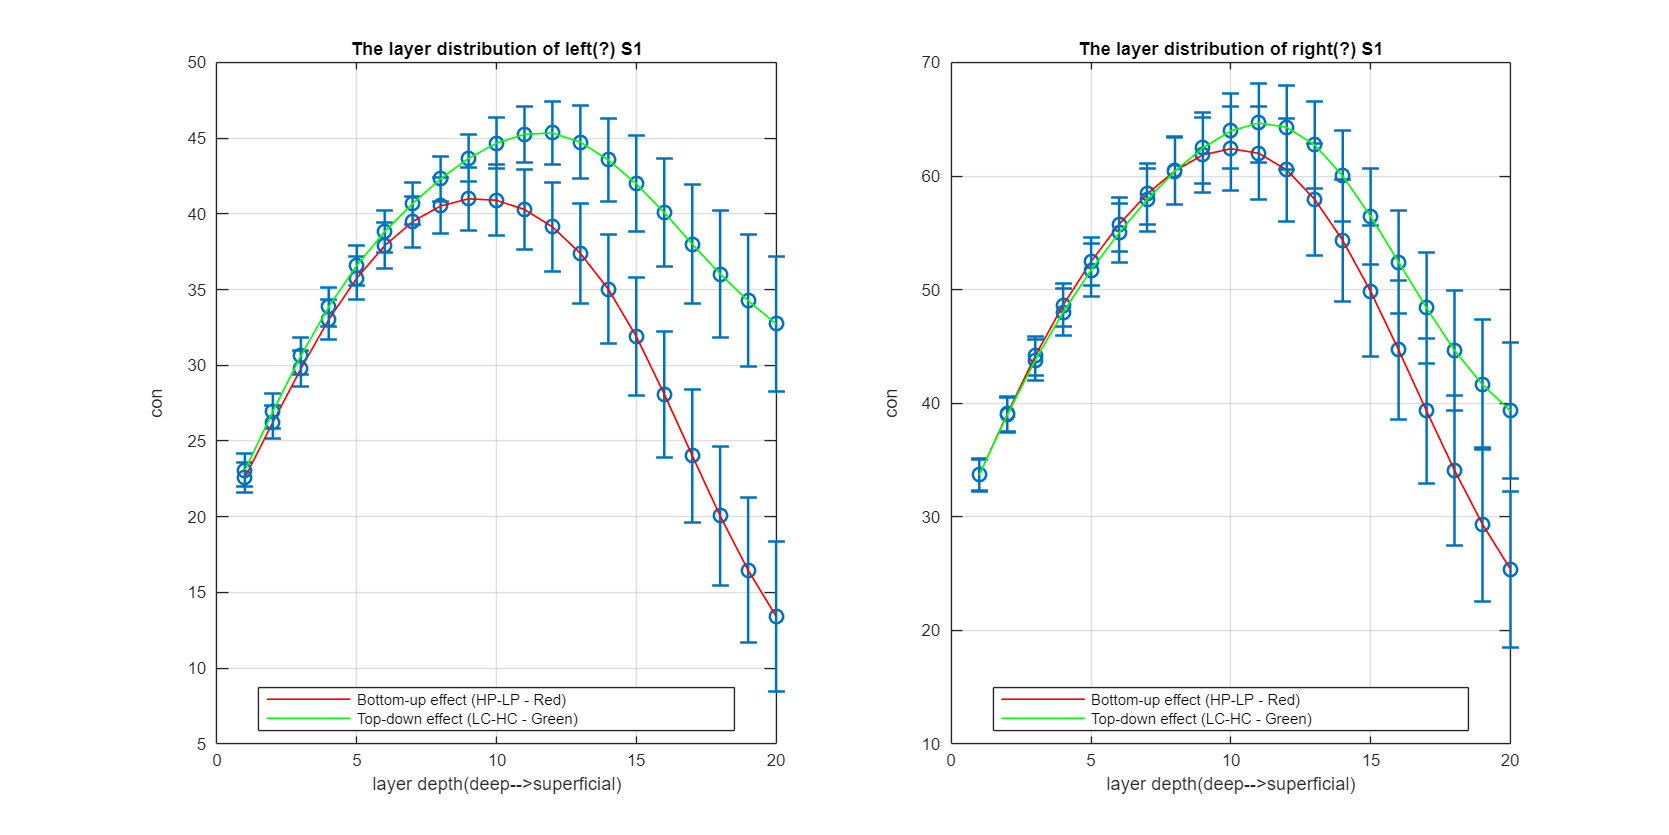

figure('Position',[100, 100, 2400, 1200]);

alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottom_beta{roitype,1}, topdown_beta{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) S1';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) S1';
        
    end
    for dataidx=1:2
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end


% allsubjlayerresp=nan

for roi=1:1
    for subj=1:length(allsubjlayer)
        HCHP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,1);
        HCLP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,2);
        LCHP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,3);
        LCLP(subj,:)=allsubjlayer{1,subj}{1,roi}.beta(:,4);

        HCHP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,1);
        HCLP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,2);
        LCHP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,3);
        LCLP_t(subj,:)=allsubjlayer{1,subj}{1,roi}.T(:,4);
        

        
        
    end
end


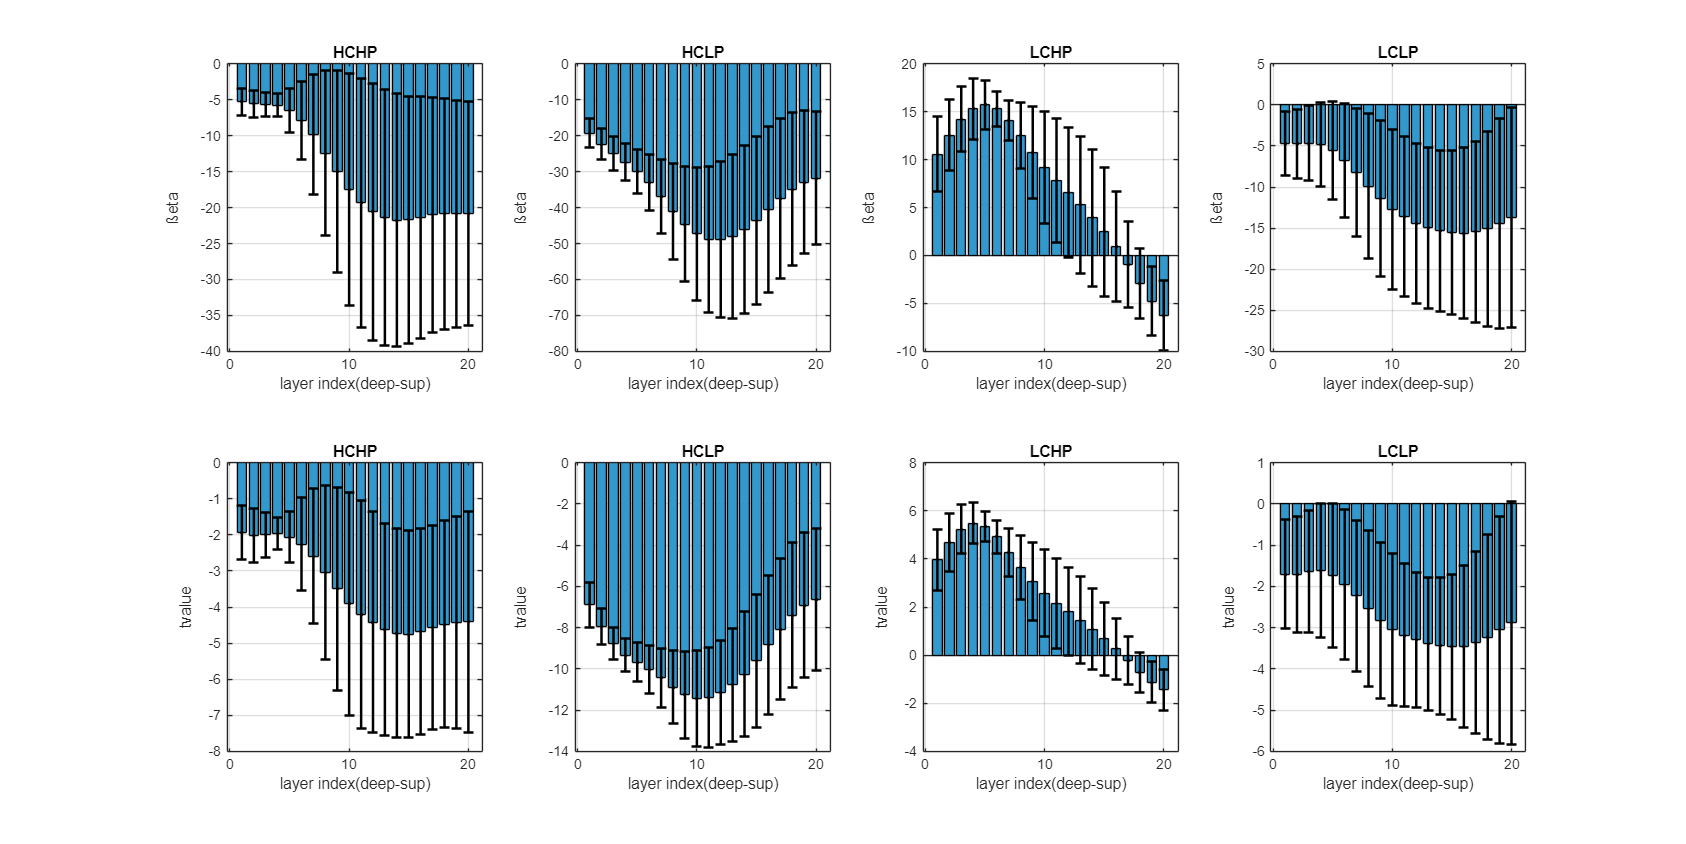

figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldata2={HCHP_t, HCLP_t,LCHP_t,LCLP_t};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for maki=1:2
    for dataidx=1:4
        %     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
        %     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
        plotidx=plotidx+1;
        if maki==1
            data=alldata{dataidx};
            yaxisnm='ßeta';
        elseif maki==2
            data=alldata2{dataidx};
            yaxisnm='tvalue';
        end
        % Example matrix of size 10x20
        %     data = allsubjlayerresp; % Random data for demonstration
        
        % Calculate column-wise mean and standard deviation
        columnMeans = mean(data, 1); % Mean of each column
        columnStdDevs = std(data, 0, 1); % Standard deviation of each column
        
        % Create the bar plot
        subplot(2,4,plotidx)
        bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
        hold on;
        
        % Add error bars
        errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
            'k.', 'LineWidth', 1.5); % Error bars in black
        
        % Customize the plot
        xlabel('layer index(deep-sup)');
        ylabel(yaxisnm);
        title(alldatanm{dataidx});
        grid on;
        hold off;
    end
end



% Example matrix of size 10x20
data = allsubjlayerresp_T; % Random data for demonstration

% Calculate column-wise mean and standard deviation
columnMeans = mean(data, 1); % Mean of each column
columnStdDevs = std(data, 0, 1); % Standard deviation of each column

% Create the bar plot
figure;
bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
hold on;

% Add error bars
errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
    'k.', 'LineWidth', 1.5); % Error bars in black

% Customize the plot
xlabel('Column Index');
ylabel('Value');
title('Bar Plot with Error Bars (Mean ± Std Dev)');
grid on;
hold off;

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);

    HCHP(subj,:)=allsubjlayer{subj}.beta(:,1,1);
    HCLP(subj,:)=allsubjlayer{subj}.beta(:,1,2);

    LCHP(subj,:)=allsubjlayer{subj}.beta(:,1,3);
    LCLP(subj,:)=allsubjlayer{subj}.beta(:,1,4);

%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end


figure;
plotidx=0;
alldata={HCHP, HCLP,LCHP,LCLP};
alldatanm={'HCHP', 'HCLP','LCHP','LCLP'};
for dataidx=1:4
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:)),2)';
%     allsubjlayerresp_T(subj,:)=mean(squeeze(allsubjlayer{subj}.T(:,:,:)),2)';
    plotidx=plotidx+1;
    data=alldata{dataidx};
% Example matrix of size 10x20
%     data = allsubjlayerresp; % Random data for demonstration
    
    % Calculate column-wise mean and standard deviation
    columnMeans = mean(data, 1); % Mean of each column
    columnStdDevs = std(data, 0, 1); % Standard deviation of each column
    
    % Create the bar plot
    subplot(2,2,plotidx)
    bar(columnMeans, 'FaceColor', [0.2 0.6 0.8]); % Bar plot with custom color
    hold on;
    
    % Add error bars
    errorbar(1:length(columnMeans), columnMeans, columnStdDevs, ...
        'k.', 'LineWidth', 1.5); % Error bars in black
    
    % Customize the plot
    xlabel('layer index(deep-sup)');
    ylabel('ßeta');
    title(alldatanm{dataidx});
    grid on;
    hold off;
end


histogram(HC_onpain)

%     {'pain_high_cogn_high_pain'   }
%     {'pain_high_cogn_low_pain'    }
%     {'pain_low_cogn_high_pain'    }
%     {'pain_low_cogn_low_pain'     }
for subj=1:length(allsubjlayer)
    HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1,1)-allsubjlayer{subj}.beta(:,1,2);
    LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,3,1)-allsubjlayer{subj}.beta(:,1,4);


%     HC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,1);
% 
%     LC_onpain(subj,:)=allsubjlayer{subj}.beta(:,1,2);
%     allsubjlayerresp(subj,:)=mean(squeeze(allsubjlayer{subj}.beta(:,:,:,1)),2)';    
end

% this is the higpain-lowpain contrast for the high and low cognition
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;

% this is the higpain-lowpain contrast for the high and low cognition
% data = HC_onpain; % Random data for demonstration
figure;
alldata={HC_onpain, LC_onpain};
for dataidx=1:2
    % Calculate column-wise mean and standard error
    data=alldata{dataidx};
    columnMeans = mean(data, 1); % Mean of each column
    columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
    
    % Create the scatter plot
    
    errorbar(1:20, columnMeans, columnStdErrors, ...
        'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
    hold on;
    
    % Connect the points with a line
    if dataidx==1
        plot(1:20, columnMeans, '-r', 'LineWidth', 1);
    else
        plot(1:20, columnMeans, '-k', 'LineWidth', 1);
    end
    
    % Customize the plot
    xlabel('layer Index');
    ylabel('Value');
    title('Scatter Plot with Standard Errors and Connecting Line');
    grid on;
end
hold off;

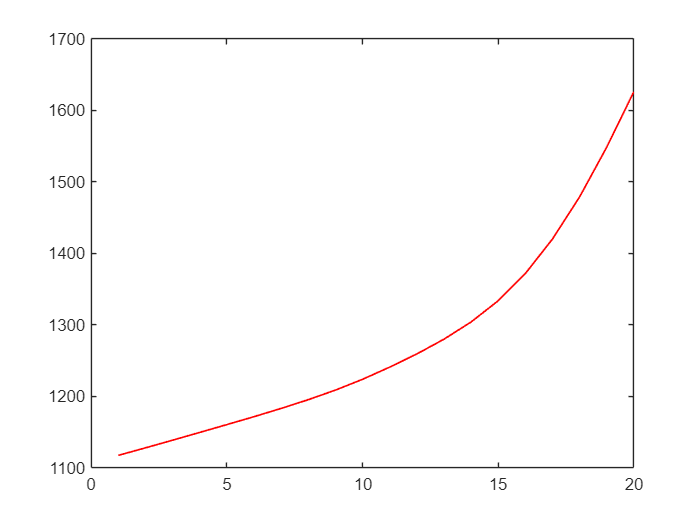

%check the bold response layerdependency
load('C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat')
figure;
vertexmean=squeeze(mean(interimdata_columns{1,2}{1,1},1));
layermean=mean(vertexmean,2)';
plot(1:20, layermean, '-r', 'LineWidth', 1);